# TITLE: Basic Modulation Concepts

Authors: Fernando Guiomar [guiomar@av.it.pt](guiomar@av.it.pt) 

Last Update: 08/11/2019

## Initialization

clear;
clear global;
close all;
clc;

% Load Libraries:
addpath(genpath('..\..\..\'));

global PROG;
PROG.showMessagesLevel = 2;
initProg();

Current Date: 10-Nov-2019 01:16:38


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%                      PROGRAM INITIALIZATION                      %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


RGB = fancyColors();

## Input Parameters

SIG.M = 16;                 % QAM constellation size
SIG.symRate = 60e9;         % total symbol-rate of the signal
SIG.modulation = 'QAM';     % modulation type [QAM/PAM]
SIG.rollOff = 0.1;          % roll-off factor
SIG.nPol = 1;               % number of polarizations
SIG.nSyms = 2^17;           % total number of simulated symbols
nSpS = 2;                   % number of samples per symbol

## Set Transmitter Parameters

#### Signal Parameters:

TX.SIG = setSignalParams('symRate',SIG.symRate,'M',SIG.M,...
    'nPol',SIG.nPol,'nBpS',log2(SIG.M),'nSyms',SIG.nSyms,...
    'roll-off',SIG.rollOff,'modulation',SIG.modulation);

#### Modulation Parameters:

TX.QAM = QAM_config(TX.SIG);

#### Bit Parameters:

TX.BIT.source = 'randi';
TX.BIT.seed = 1;

#### Pulse Shaping Filter Parameters:

TX.PS.type = 'RRC';
TX.PS.rollOff = TX.SIG.rollOff;
TX.PS.nTaps = 128;

#### DAC Parameters:

TX.DAC.RESAMP.sampRate = nSpS*TX.SIG.symRate;

## Generate Tx Bits

TX.BIT.txBits = Tx_generateBits(SIG.nSyms,TX.QAM.M,TX.QAM.nPol,TX.BIT);

## Generate Transmitted Symbols

[S.tx,TX.BIT.txSyms] = Tx_QAM(TX.QAM,TX.BIT.txBits);

#### Plot Transmitted Constellation Symbols:

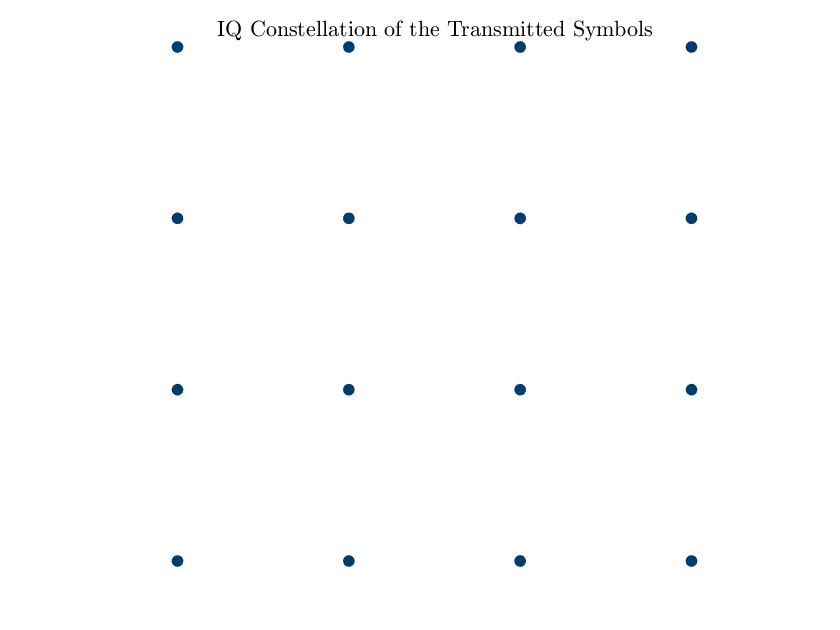

scatterPlot(S.tx,'markersize:sig',20);
title('IQ Constellation of the Transmitted Symbols','interp','latex')

## Pulse Shaping

[S.txSC,TX.PS] = pulseShaper(S.tx,nSpS,TX.PS);

#### Plot Pulse Shaping Taps:

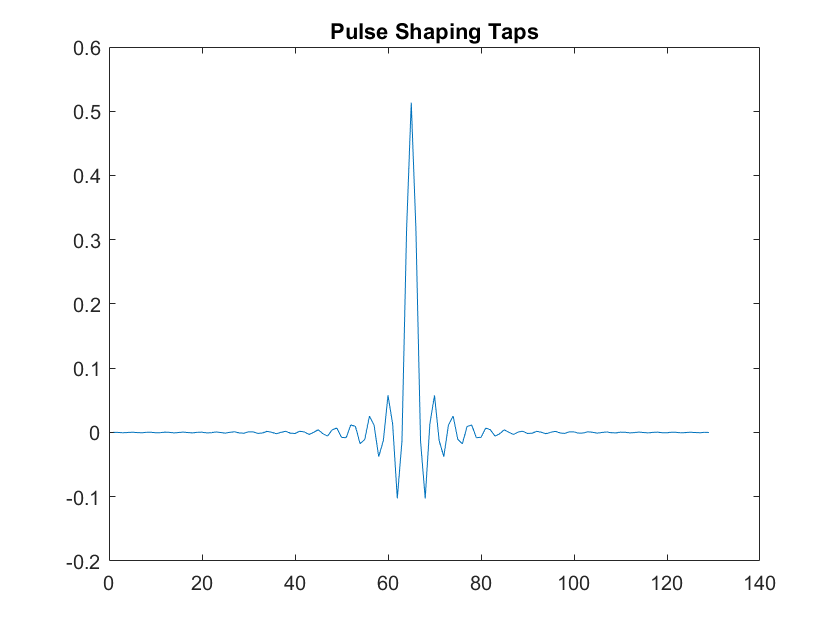

figure();
plot(TX.PS.W);
title('Pulse Shaping Taps')

#### Plot Signal Spectrum:

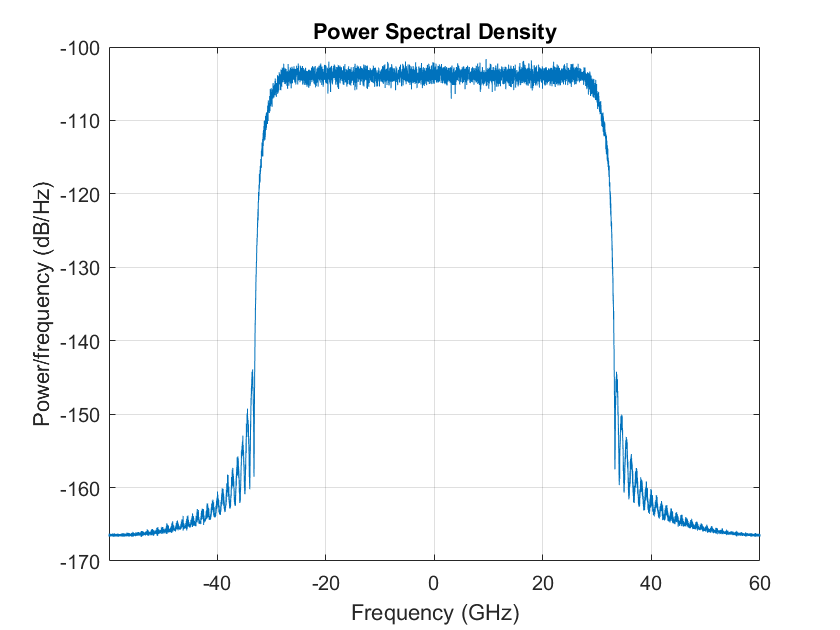

figure();
pwelch(S.txSC(1,:),1e4,[],[],TX.DAC.RESAMP.sampRate,'centered')

#### Plot Time-Domain Signal:

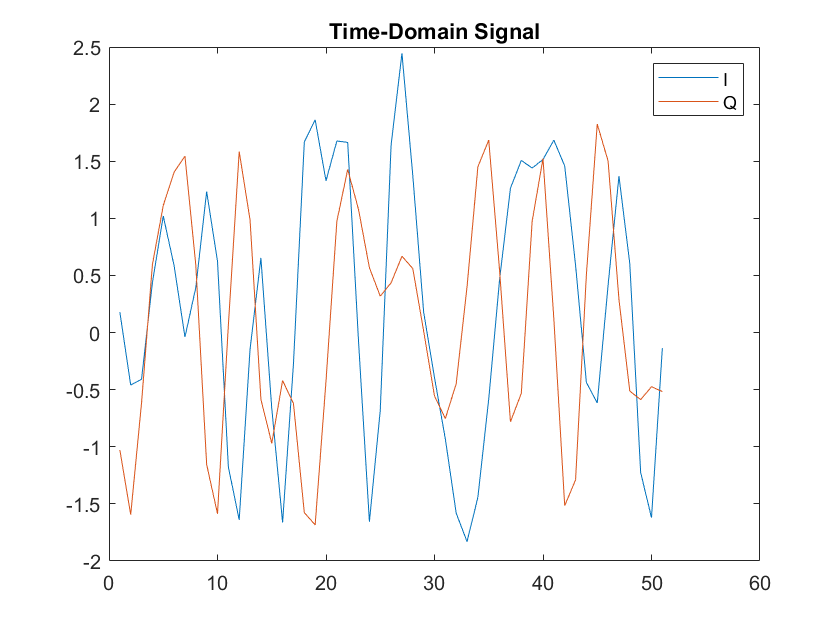

figure();
ni = 50;
nf = 100;
plot(real(S.txSC(1,ni:nf)));
hold on;
plot(imag(S.txSC(1,ni:nf)));
hold off;
legend('I','Q')
title('Time-Domain Signal')

#### Plot Time-Domain Signal Constellation with Oversampling:

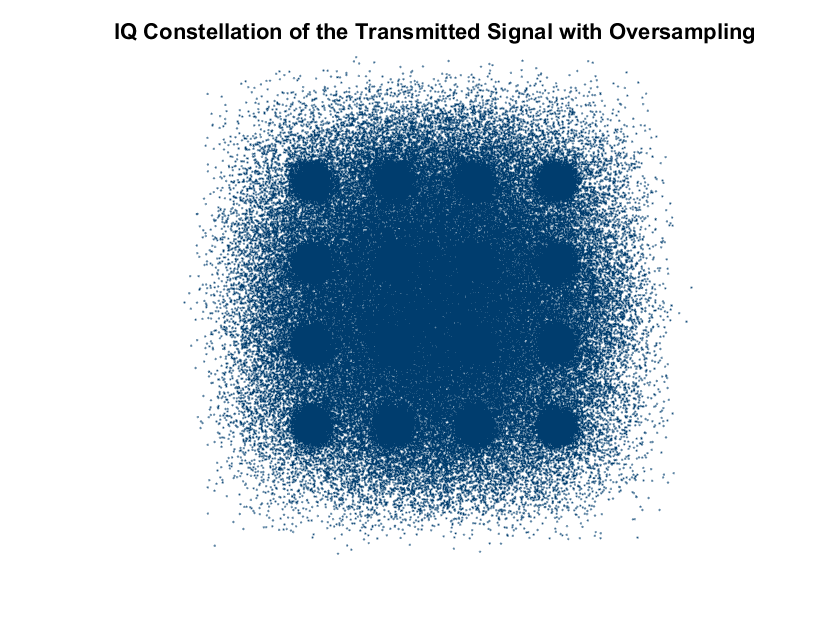

scatterPlot(S.txSC(1,:));
title('IQ Constellation of the Transmitted Signal with Oversampling')

## Plot Time-Domain Signal Constellation after Downsampling

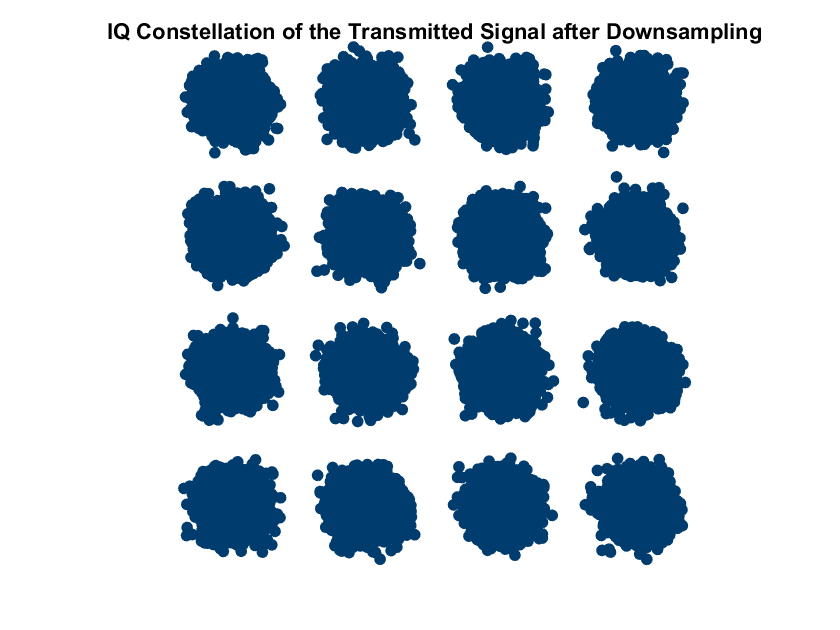

scatterPlot(S.txSC(1,1:nSpS:end),'markersize:sig',20);
title('IQ Constellation of the Transmitted Signal after Downsampling')

## Exit PROG

exitProg();



Total Elapsed Time: 14.2742 [s]

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%                               END                                %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
